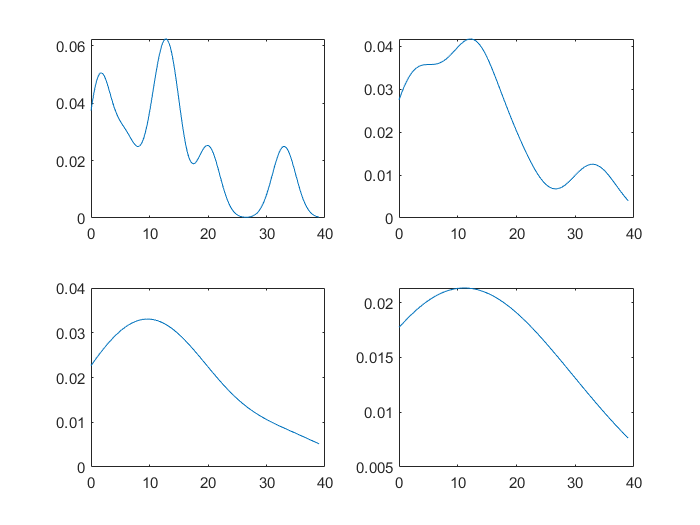

data = [1, 2, 6, 11, 13, 14, 20, 33];
k =0;
for hn = [2,4,8,16]
    k= k +1;
x = 0:0.1:39;
for i = 1 : 391
   mysum = 0;
   for j = 1 : 8
       mysum = mysum + 1/hn*myGaussianK((x(i)-data(j))/hn);
   end
   pn(k,i) = 1/8 * mysum;
end
end
figure;
subplot(2,2,1);
plot(x,pn(1,:));
subplot(2,2,2);
plot(x,pn(2,:));
subplot(2,2,3);
plot(x,pn(3,:));
subplot(2,2,4);
plot(x,pn(4,:));

function [y] = K(u)
% window function
    [d,~]=size(u);
    y = 1;
    for idx = 1:d
        if abs(u(idx))>1/2
            y = 0;
        end
    end
end

function [y] = myGaussianK(u)
% Gaussian kernel
    y = 1/sqrt(2*pi)*exp(-norm(u)^2/2);
end